## Simulación ideal

Definición de parámetros para la simulación.

tPWM = 1e-3;
Vmax = 12;

### Comprobación de encoders

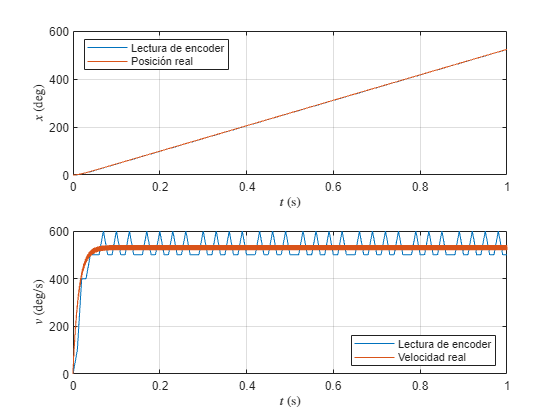

voltage = 6;
tf = 1;
stepTime = 0;
open('simIdeal.slx')
simOut = sim('simIdeal.slx');
timeReal = simOut.tout;
timePos = simOut.yout{1}.Values.Time;
angPos = simOut.yout{1}.Values.Data;
timeVel = simOut.yout{2}.Values.Time;
angVel = simOut.yout{2}.Values.Data;
angPosReal = simOut.yout{3}.Values.Data;
angVelReal = simOut.yout{4}.Values.Data;
figure
subplot(2,1,1)
plot(timePos,angPos)
hold on
plot(timeReal,angPosReal)
grid on
legend('Lectura de encoder','Posición real',Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$x$ (deg)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(timeVel,angVel)
hold on
plot(timeReal,angVelReal)
grid on
legend('Lectura de encoder','Velocidad real',Location="southeast")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$v$ (deg/s)', Interpreter='latex')
xlim([0 1])

% exportgraphics(gcf,'figuras\comprobacionEncoders.pdf')

### Comparación con los datos reales

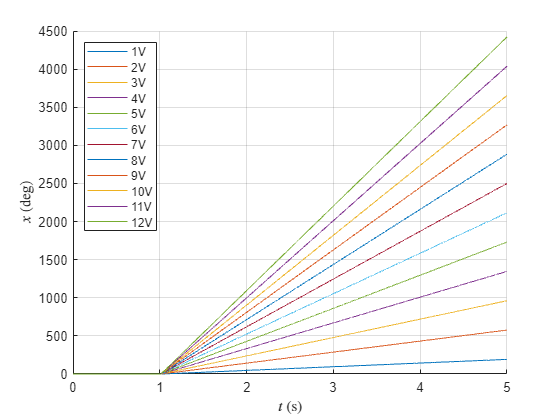

tf = 5;
stepTime = 1;
figure(27)
clf
hold on

figure(34)
clf
hold on
for i = 1:12
    voltage = i;
    simOut = sim('simIdeal.slx');
    timePos = simOut.yout{1}.Values.Time;
    angPos = simOut.yout{1}.Values.Data;
    timeVel = simOut.yout{2}.Values.Time;
    angVel = simOut.yout{2}.Values.Data;
    figure(27)
    plot(timePos, angPos, DisplayName=strcat(num2str(voltage),'V'))
    figure(34)
    plot(timeVel, angVel, DisplayName=strcat(num2str(voltage),'V'))
end
figure(27)
grid on
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$x$ (deg)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\posicionIdealEncoder.pdf')

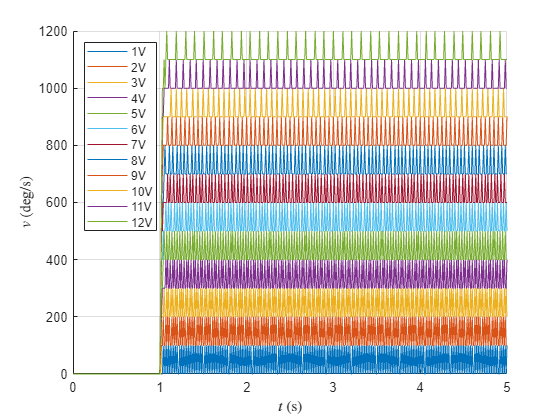

figure(34)
grid on
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$v$ (deg/s)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\velocidadIdealEncoder.pdf')